s= tf("s");
G= 10/(s*(0.5*s +1)*(0.1*s + 1))

G =
 
            10
  ----------------------
  0.05 s^3 + 0.6 s^2 + s
 
Continuous-time transfer function.
Model Properties



z= sqrt( (log(0.2)^2) / (pi^2 + log(0.2)^2 ))

z = 0.4559


s1 = sqrt((-2*z*z) + sqrt(1 + (4*z*z)) )

s1 = 0.9683

PM = atan((2*z)/s1) *180/pi

PM = 43.2823


PM1 = PM +15 %PM +10

PM1 = 58.2823

PM2 = PM1 *pi/180

PM2 = 1.0172

a = (1 - sin(PM2)) / (1+sin(PM2))

a = 0.0807


db = 20*log10(1/sqrt(a))

db = 10.9312

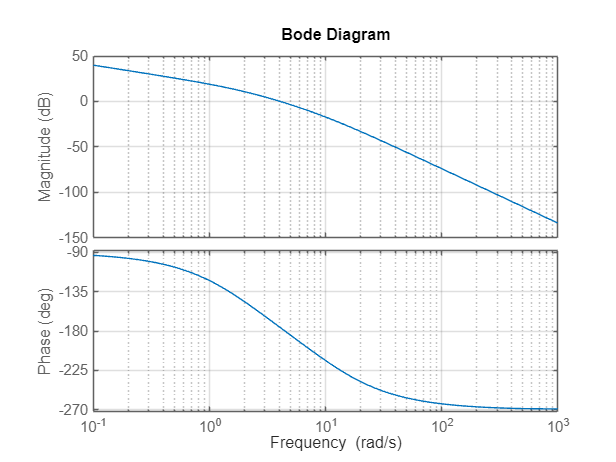

bode(G)
grid on


wc = 7.37; %6.9
T = 1/(wc * sqrt(a));
zc = 1/T

zc = 2.0937

pc = 1/(a*T)

pc = 25.9433


Gc = (s+zc)/(a*(s+pc))

Gc =
 
     s + 2.094
  ----------------
  0.0807 s + 2.094
 
Continuous-time transfer function.
Model Properties


%bode(Gc)


Gf = G * Gc

Gf =
 
                   10 s + 20.94
  -----------------------------------------------
  0.004035 s^4 + 0.1531 s^3 + 1.337 s^2 + 2.094 s
 
Continuous-time transfer function.
Model Properties


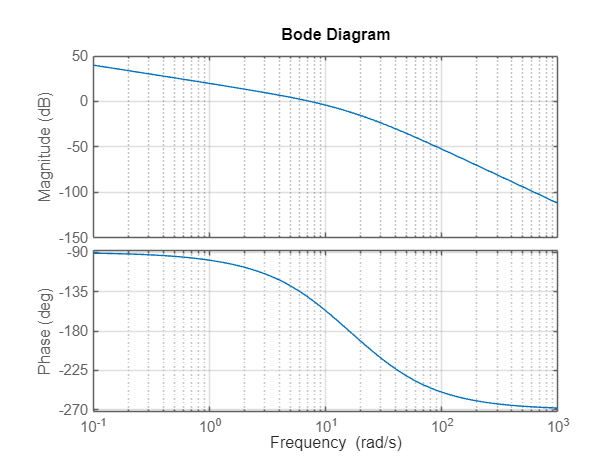

bode(Gf)
grid on

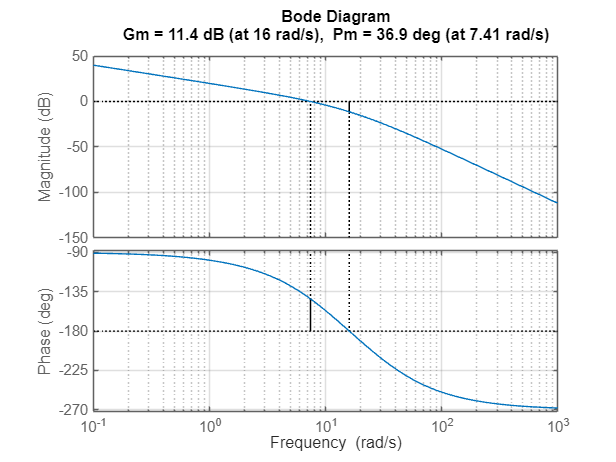

margin(Gf)
grid on

Tf = feedback(Gf,1)

Tf =
 
                       10 s + 20.94
  -------------------------------------------------------
  0.004035 s^4 + 0.1531 s^3 + 1.337 s^2 + 12.09 s + 20.94
 
Continuous-time transfer function.
Model Properties


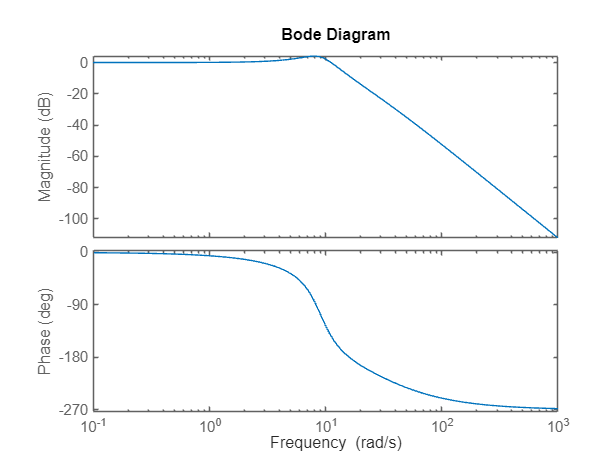

bode(Tf)

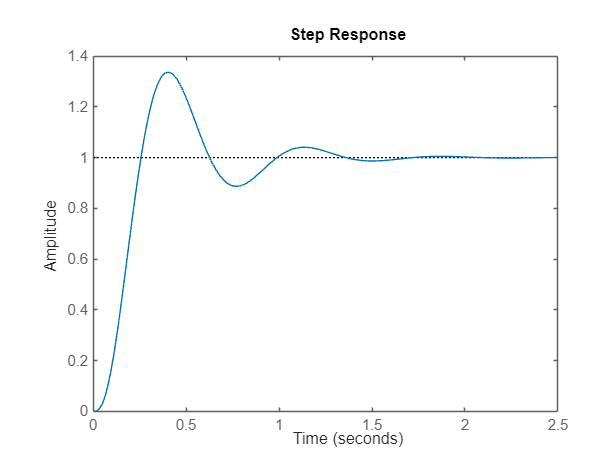

step(Tf)

beta = 2.1134

beta = 2.1134

w =4.14%4.5

w = 4.1400

t = 4/w

t = 0.9662


w1 = 1/t %1/t

w1 = 1.0350

w2 = 1/(beta*t)

w2 = 0.4897

Gl= (s + w1) / (beta*(s+w2))

Gl =
 
     s + 1.035
  ---------------
  2.113 s + 1.035
 
Continuous-time transfer function.
Model Properties


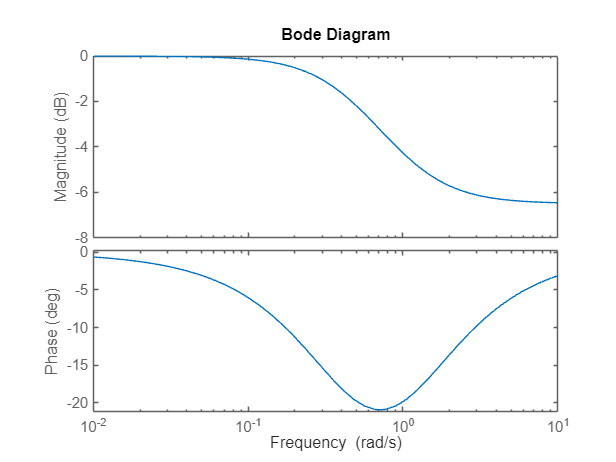

bode(Gl)

Gf2 = Gf * Gl

Gf2 =
 
                   10 s^2 + 31.29 s + 21.67
  -----------------------------------------------------------
  0.008528 s^5 + 0.3277 s^4 + 2.984 s^3 + 5.808 s^2 + 2.167 s
 
Continuous-time transfer function.
Model Properties


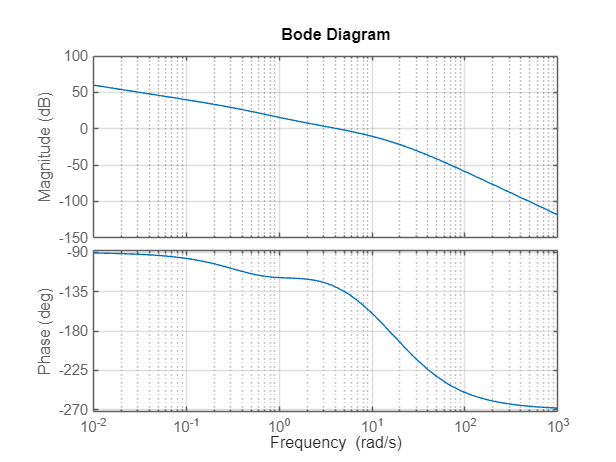

bode(Gf2)
grid on

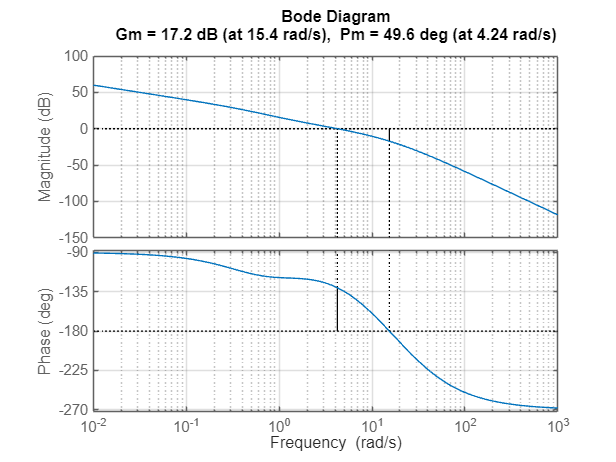


margin(Gf2)
grid on

Tf2 = feedback(Gf2,1)

Tf2 =
 
                       10 s^2 + 31.29 s + 21.67
  -------------------------------------------------------------------
  0.008528 s^5 + 0.3277 s^4 + 2.984 s^3 + 15.81 s^2 + 33.45 s + 21.67
 
Continuous-time transfer function.
Model Properties


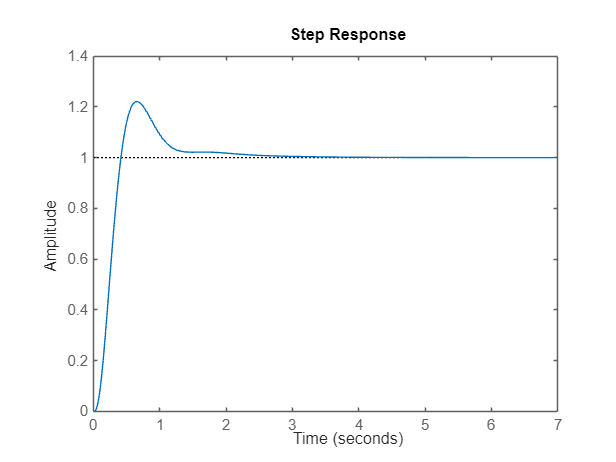

step(Tf2)

detl = stepinfo(Tf2)

detl = struct with fields:
         RiseTime: 0.2650
    TransientTime: 1.8808
     SettlingTime: 1.8808
      SettlingMin: 0.9099
      SettlingMax: 1.2208
        Overshoot: 22.0813
       Undershoot: 0
             Peak: 1.2208
         PeakTime: 0.6546


ans = 1